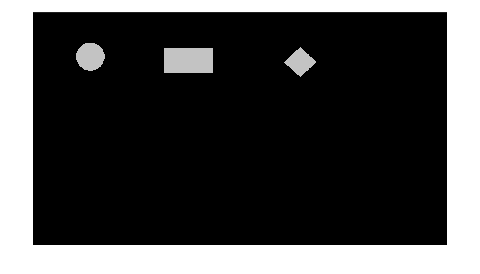

% Ex1
clear variables

im = imread('Objects.png');
imshow(im)

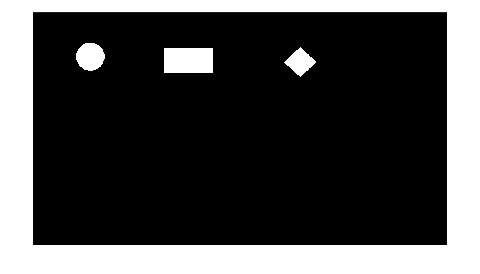

if(~islogical(im))
if(ndims(im) > 2), im = rgb2gray(im); end
level = graythresh(im); BW = im2bw(im,level);
else
BW = im;
end
figure , imshow(BW)

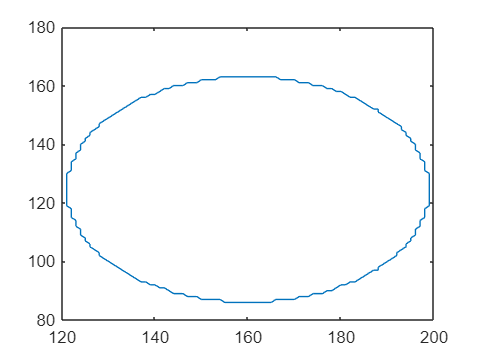

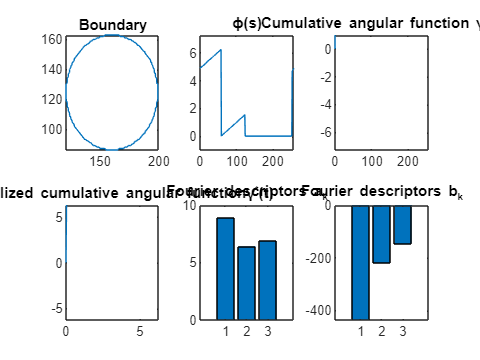

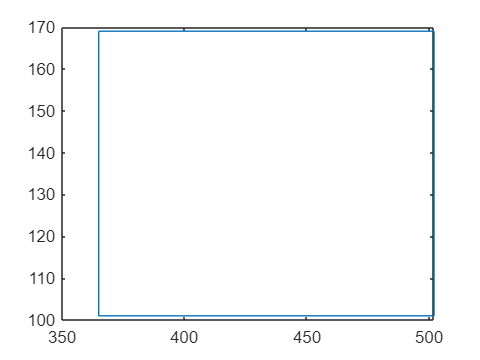

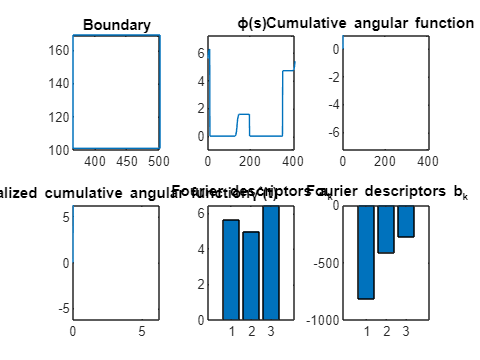

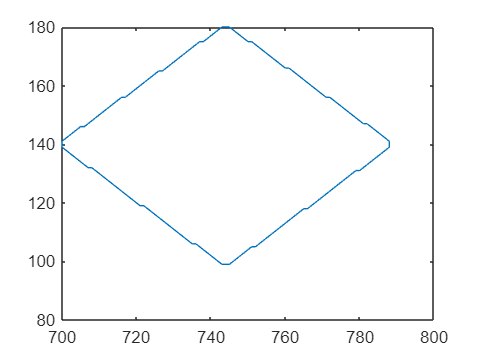

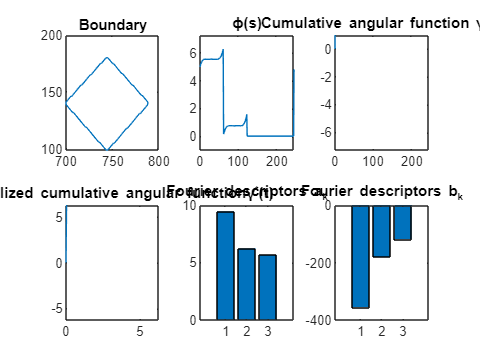

N = 10;
[B,L,N] = bwboundaries(BW,'noholes');
for k = 1:N
    X = B{k}(:,2);
    Y = B{k}(:,1);
    contur = [X'; Y'];
    figure, plot(X, Y);
    angularFunctionDescriptors(contur, N);
end


% Observation: No disturbances occur for higher values of N